#### Reinitialize

clear
clc
load_data
load_shadow
lookuptable
home = pwd();

shadow_map = custom_colormap(1, "shadows");
spectrum1_map = custom_colormap(1, "spectrum1");
greens = custom_colormap(1,"greens");
blues = custom_colormap(1, "blues");
reds = custom_colormap(1, "reds");
cyans= custom_colormap(1, "cyans");
pinks = custom_colormap(1, "pinks");
cmaps_simple = cat(3, greens,blues,reds,cyans,pinks);

bin_size = 200; % in microns
side = "right";  
sigma = 1;

subjects = fieldnames(data);

aspect_multiplier = 1;
xaspect = fixed.xmax/fixed.xmax;
yaspect = fixed.ymax/fixed.xmax;
zaspect = fixed.zmax/fixed.xmax;

n_bins_x = round(shadow.(side).x_range / bin_size, 0);
n_bins_y = round(shadow.(side).y_range / bin_size, 0);
n_bins_z = round(shadow.(side).z_range / bin_size, 0);

x_data_combined = [];
y_data_combined = [];
z_data_combined = [];

x_bin_edges = shadow.(side).x_bounds(1):bin_size:shadow.(side).x_bounds(2);
y_bin_edges = shadow.(side).y_bounds(1):bin_size:shadow.(side).y_bounds(2);
z_bin_edges = shadow.(side).z_bounds(1):bin_size:shadow.(side).z_bounds(2);

x_histo_values_combined = zeros(numel(subjects), length(x_bin_edges)-1);
y_histo_values_combined = zeros(numel(subjects), length(y_bin_edges)-1);
z_histo_values_combined = zeros(numel(subjects), length(z_bin_edges)-1);

% Create 3D variable to store histograms
xy_cells_hist_combined = zeros(n_bins_x,n_bins_y,numel(subjects));
yz_cells_hist_combined = zeros(n_bins_y,n_bins_z,numel(subjects));
xz_cells_hist_combined = zeros(n_bins_x,n_bins_z,numel(subjects));

% Create 3D variable to store normalized histograms
xy_cells_normhist_combined = zeros(n_bins_x,n_bins_y,numel(subjects));
yz_cells_normhist_combined = zeros(n_bins_y,n_bins_z,numel(subjects));
xz_cells_normhist_combined = zeros(n_bins_x,n_bins_z,numel(subjects));

% Create 3D variable to gaussian filtered histograms
xy_cells_filtered_combined = zeros(n_bins_x,n_bins_y,numel(subjects));
yz_cells_filtered_combined = zeros(n_bins_y,n_bins_z,numel(subjects));
xz_cells_filtered_combined = zeros(n_bins_x,n_bins_z,numel(subjects));

for i = 1:numel(subjects)
    s = subjects{i};
    %cmap_to_use = cmaps_simple(:,:,i);
    cmap_to_use = reds;

Individual 1D Histograms


    individual_axes = figure;
    
    % X Histogram
    subplot(3,1,1);
    x_data = data.(s).raw(:,x);
    x_histo = histogram(x_data, 'BinEdges', x_bin_edges);
    x_histo_values = x_histo.Values;
    x_histo_values_combined(i,:) = x_histo_values;
    title("Rostral -> Caudal")
    ylabel("Cells")

    % Y Histogram
    subplot(3,1,2);
    y_data = data.(s).raw(:,y);
    y_histo = histogram(y_data, 'BinEdges', y_bin_edges);
    y_histo_values = y_histo.Values;
    y_histo_values_combined(i,:) = y_histo_values;
    title("Dorsal -> Ventral")
    ylabel("Cells")

    % Z Histogram
    subplot(3,1,3);
    z_data = data.(s).raw(:,z);
    z_histo = histogram(z_data, 'BinEdges', z_bin_edges);
    z_histo_values = z_histo.Values;
    z_histo_values_combined(i,:) = z_histo_values;
    title("Left -> Right")
    ylabel("Cells")

    sgtitle(strrep(s, "_", "\_"))


Individual 2D Histograms

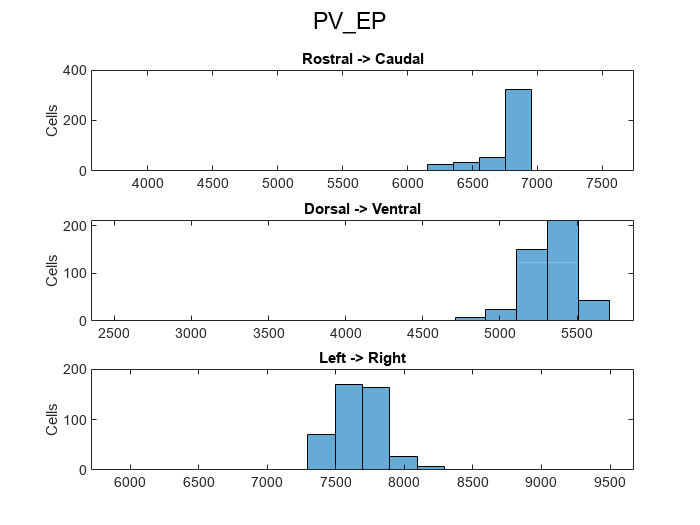

cb =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 26]
    FontSize: 9
    Position: [0.8148 0.2155 0.0381 0.5708]
       Units: 'normalized'

  Show all properties


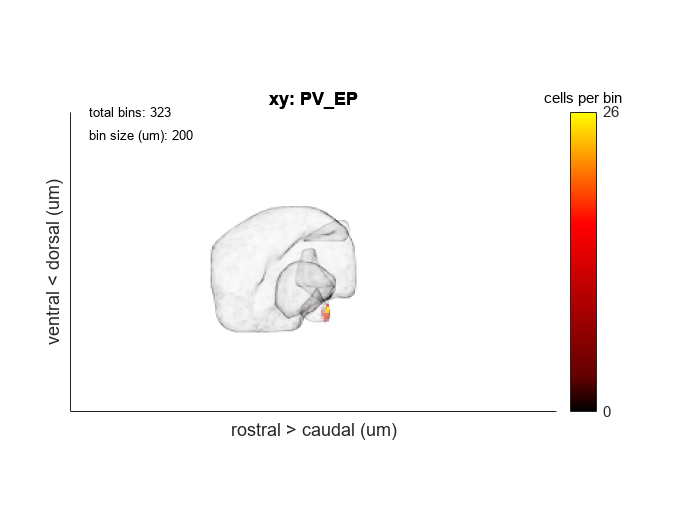

cb =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 23]
    FontSize: 9
    Position: [0.8148 0.1755 0.0381 0.6510]
       Units: 'normalized'

  Show all properties


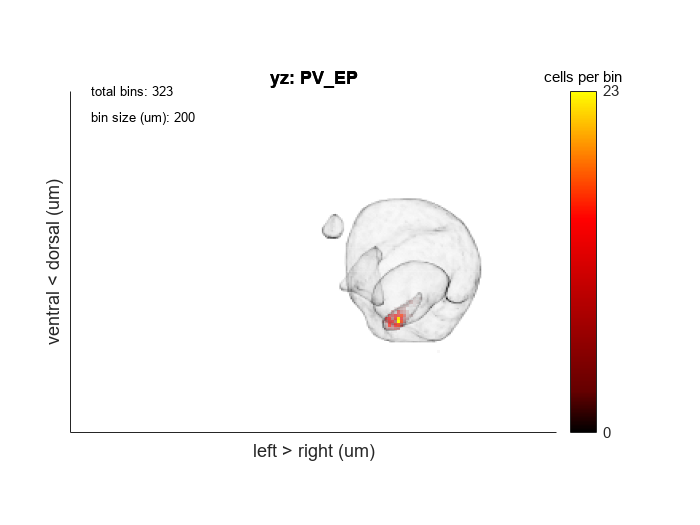

cb =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 22]
    FontSize: 9
    Position: [0.7348 0.1222 0.0381 0.6965]
       Units: 'normalized'

  Show all properties


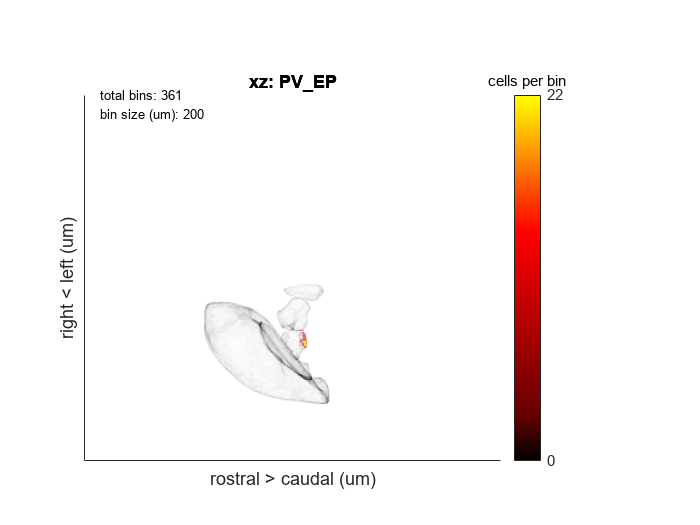

    
    %_XY_______________________________________________________________________________________________________________
    xy = figure;
    
    xy_shadow = axes('Position', [0.1, 0.1, 0.8, 0.8]);
    hist3(shadow.(side).xy, [100, 100], 'CdataMode', "auto", 'EdgeColor', 'none');
    colormap(xy_shadow, shadow_map);
    ylim([0, fixed.ymax]);
    xlim([0, fixed.xmax]);
    yticks([]);
    xticks([]);
    pbaspect([xaspect yaspect 1]); % [x,y,z] of plot
    view(2);
    set(xy_shadow, 'YDir', 'reverse');
    set(xy_shadow, 'Layer', 'bottom');
    cb = colorbar;
    cb.Ticks = [];
    grid off;
    
    % Data Plot
    xy_cells = axes('Position', [0.1, 0.1, 0.8, 0.8]);
    
    xy_cells_hist = hist3([data.(s).raw(:,x), data.(s).raw(:,y)], [n_bins_x, n_bins_y]);
    xy_cells_normhist = xy_cells_hist / max(xy_cells_hist(:));
    xy_cells_filtered = imgaussfilt(xy_cells_normhist, sigma);

    xy_cells_hist_combined(:,:,i) = xy_cells_hist;
    xy_cells_normhist_combined(:,:,i) = xy_cells_normhist;
    xy_cells_filtered_combined(:,:,i) = xy_cells_filtered;

    hist3([data.(s).raw(:,x), data.(s).raw(:,y)], [n_bins_x, n_bins_y], 'CdataMode', "auto", 'EdgeColor', 'none');
    colormap(xy_cells, cmap_to_use);
    surface_handle = findobj(xy_cells, 'Type', 'surface');
    surface_handle.AlphaData = surface_handle.CData;
    surface_handle.AlphaDataMapping = 'scaled';
    surface_handle.FaceAlpha = 'flat';
    xlabel("rostral > caudal (um)")
    ylabel("ventral < dorsal (um)")
    ylim([0, fixed.ymax]);
    xlim([0, fixed.xmax]);
    yticks([]);
    xticks([]);
    pbaspect([xaspect yaspect 1]); % [x,y,z] of plot
    view(2);
    set(xy_cells, 'YDir', 'reverse');
    set(xy_cells, 'Color', 'none');
    cb = colorbar;
    cb.Ticks = ([0,max(xy_cells_hist(:))])
    cb.Title.String = "cells per bin";
    % Report on plot
    
    title(xy_shadow, "xy: " + strrep(s, "_", "\_"));
    title(xy_cells, "xy: " + strrep(s, "_", "\_"));

    total_bins = n_bins_x * n_bins_y;
    text(500, 0, 'total bins: ' + string(total_bins), 'FontSize', 8, 'Color', 'black', 'BackgroundColor', 'white');
    text(500, 600, 'bin size (um): ' + string(bin_size), 'FontSize', 8, 'Color', 'black', 'BackgroundColor', 'white');
    
    %_yz_______________________________________________________________________________________________________________

    yz = figure;
    % Shadow
    yz_shadow = axes('Position', [0.1, 0.1, 0.8, 0.8]);
    hist3([shadow.(side).yz(:,2) shadow.(side).yz(:,1)], [100, 100], 'CdataMode', "auto",  'EdgeColor', 'none');
    colormap(yz_shadow, shadow_map);
    ylim([0 fixed.ymax]);
    xlim([0 fixed.zmax]);
    yticks([]);
    xticks([]);
    pbaspect([zaspect yaspect 1]); % [x,y,z] of plot
    view(2);
    set(yz_shadow, 'YDir', 'reverse');
    set(yz_shadow, 'Layer', 'bottom');
    cb = colorbar;
    cb.Ticks = [];
    grid off;
    
    % Data Plot
    yz_cells = axes('Position', [0.1, 0.1, 0.8, 0.8]);
    
    yz_cells_hist = hist3([data.(s).raw(:,y), data.(s).raw(:,z)], [n_bins_y, n_bins_z]);
    yz_cells_normhist = yz_cells_hist / max(yz_cells_hist(:));
    yz_cells_filtered = imgaussfilt(yz_cells_normhist, sigma);

    yz_cells_hist_combined(:,:,i) = yz_cells_hist;
    yz_cells_normhist_combined(:,:,i) = yz_cells_normhist;
    yz_cells_filtered_combined(:,:,i) = yz_cells_filtered;

    hist3([data.(s).raw(:,3), data.(s).raw(:,2)], [n_bins_z, n_bins_y], 'CdataMode', "auto", 'EdgeColor', 'none');
    colormap(yz_cells, cmap_to_use);
    surface_handle = findobj(yz_cells, 'Type', 'surface');
    surface_handle.AlphaData = surface_handle.CData;
    surface_handle.AlphaDataMapping = 'scaled';
    surface_handle.FaceAlpha = 'flat';
    xlabel("left > right (um)")
    ylabel("ventral < dorsal (um)")
    ylim([0 fixed.ymax]);
    xlim([0 fixed.zmax]);
    yticks([]);
    xticks([]);
    pbaspect([zaspect yaspect 1]); % [x,y,z] of plot
    view(2);
    set(yz_cells, 'YDir', 'reverse');
    set(yz_cells, 'Color', 'none');
    cb = colorbar;
    cb.Ticks = ([0,max(yz_cells_hist(:))])
    cb.Title.String = "cells per bin";
    
    title(yz_shadow, "yz: " + strrep(s, "_", "\_"));
    title(yz_cells, "yz: " + strrep(s, "_", "\_"));
    
    total_bins = n_bins_z * n_bins_y;
    text(500, 0, 'total bins: ' + string(total_bins), 'FontSize', 8, 'Color', 'black', 'BackgroundColor', 'white');
    text(500, 600, 'bin size (um): ' + string(bin_size), 'FontSize', 8, 'Color', 'black', 'BackgroundColor', 'white');
    
    %_xz_______________________________________________________________________________________________________________
    xz = figure;
    
    % Shadow Plot
    xz_shadow = axes('Position', [0.12, 0.12, 0.7, 0.7]);
    hist3(shadow.(side).xz, [100, 100], 'CdataMode', "auto",  'EdgeColor', 'none');
    colormap(xz_shadow, shadow_map);
    ylim([0 fixed.zmax]);
    xlim([0 fixed.xmax]);
    yticks([]);
    xticks([]);
    pbaspect([1 (fixed.zmax/fixed.xmax) 1]);
    view(2);
    set(xz_shadow, 'YDir', 'reverse');
    set(xz_shadow, 'Layer', 'bottom');
    cb = colorbar;
    cb.Ticks = [];
    grid off;
    
    % Data Plot
    xz_cells = axes('Position', [0.12, 0.12, 0.7, 0.7]);

    xz_cells_hist = hist3([data.(s).raw(:,x), data.(s).raw(:,z)], [n_bins_x, n_bins_z]);
    xz_cells_normhist = xz_cells_hist / max(xz_cells_hist(:));
    xz_cells_filtered = imgaussfilt(xz_cells_normhist, sigma);

    xz_cells_hist_combined(:,:,i) = xz_cells_hist;
    xz_cells_normhist_combined(:,:,i) = xz_cells_normhist;
    xz_cells_filtered_combined(:,:,i) = xz_cells_filtered;

    xz_cells_hist_combined(:,:,i) = xz_cells_hist;
    hist3([data.(s).raw(:,1), data.(s).raw(:,3)], [n_bins_x, n_bins_z], 'CdataMode', "auto", 'EdgeColor', 'none');
    colormap(xz_cells, cmap_to_use);
    surface_handle = findobj(xz_cells, 'Type', 'surface');
    surface_handle.AlphaData = surface_handle.CData;
    surface_handle.AlphaDataMapping = 'scaled';
    surface_handle.FaceAlpha = 'flat';
    xlabel("rostral > caudal (um)")
    ylabel("right < left (um)")
    ylim([0 fixed.zmax]);
    xlim([0 fixed.xmax]);
    yticks([]);
    xticks([]);
    pbaspect([1 (fixed.zmax/fixed.xmax) 1]);
    view(2);
    set(xz_cells, 'YDir', 'reverse');
    set(xz_cells, 'Color', 'none');
    cb = colorbar;
    cb.Ticks = ([0,max(xz_cells_hist(:))])
    cb.Title.String = "cells per bin";
    
    title(xz_shadow, "xz: " + strrep(s, "_", "\_"));
    title(xz_cells, "xz: " + strrep(s, "_", "\_"));
    
    total_bins = n_bins_x * n_bins_z;
    text(500, 0, 'total bins: ' + string(total_bins), 'FontSize', 8, 'Color', 'black', 'BackgroundColor', 'white');
    text(500, 600, 'bin size (um): ' + string(bin_size), 'FontSize', 8, 'Color', 'black', 'BackgroundColor', 'white');


    % Saving the raw data
    x_data_combined = [x_data_combined; data.(s).raw(:,x)];
    y_data_combined = [y_data_combined; data.(s).raw(:,y)];
    z_data_combined = [z_data_combined; data.(s).raw(:,z)];
end

## **1D Histograms**

### X

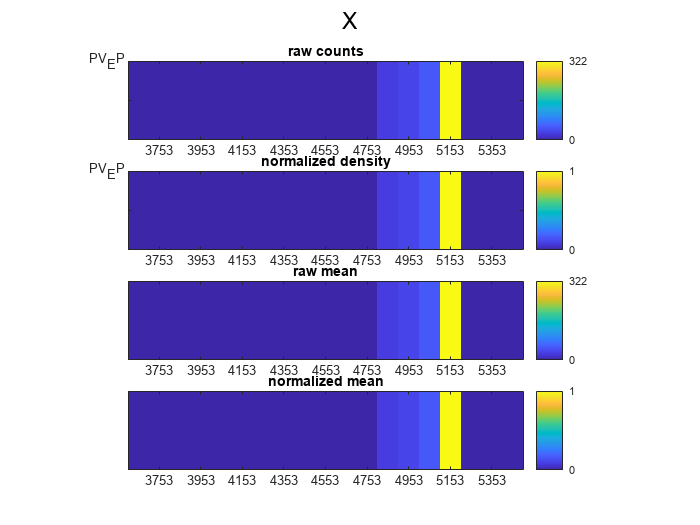

x_histo_values_combined_normalized = zeros(size(x_histo_values_combined));

num_subjects = size(x_histo_values_combined,1);
for i=1:num_subjects
    new_norm = x_histo_values_combined(i,:)/max(x_histo_values_combined(i,:));
    x_histo_values_combined_normalized(i,:) = new_norm;
end

figure;
% RAW
subplot(4,1,1);
imagesc(x_histo_values_combined);
title("raw counts");
cb = colorbar;
cb.Ticks = [0,max(x_histo_values_combined(:))];
pbaspect([1 0.2 1]);
yticklabels(subjects);
xticklabels(x_bin_edges);
% NORMALIZED
subplot(4,1,2);
imagesc(x_histo_values_combined_normalized);
title("normalized density");
cb = colorbar;
cb.Ticks = [0,1];
pbaspect([1 0.2 1]);
yticklabels(subjects);
xticklabels(x_bin_edges);
%RAW MEAN
subplot(4,1,3);
x_histo_values_combined_mean = mean(x_histo_values_combined, 1);
imagesc(x_histo_values_combined_mean);
title("raw mean");
cb = colorbar;
cb.Ticks = [0,max(x_histo_values_combined(:))];
clim([0,max(x_histo_values_combined(:))])
pbaspect([1 0.2 .1]);
yticks([]);
xticklabels(x_bin_edges);
% NORMALIZED MEAN
subplot(4,1,4);
x_histo_values_combined_normalized_mean = mean(x_histo_values_combined_normalized, 1);
imagesc(x_histo_values_combined_normalized_mean);
title("normalized mean");
cb = colorbar;
cb.Ticks = [0,1];
clim([0,max(x_histo_values_combined_normalized(:))])
pbaspect([1 0.2 1]);
yticks([]);
xticklabels(x_bin_edges);
sgtitle("X")

### Y

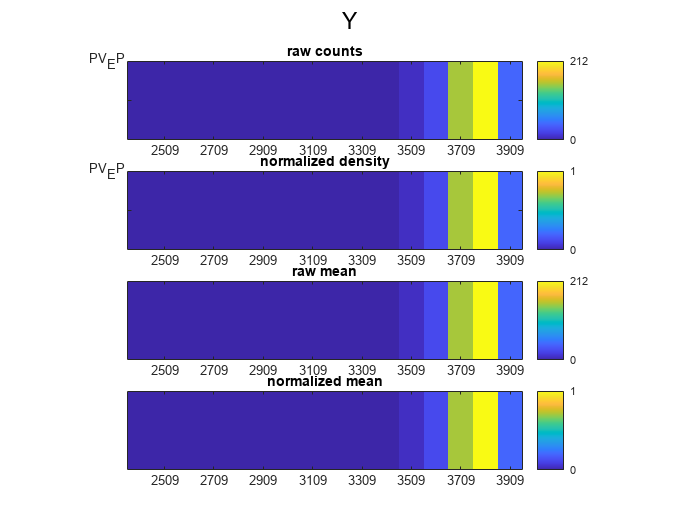

y_histo_values_combined_normalized = zeros(size(y_histo_values_combined));

num_subjects = size(y_histo_values_combined,1);
for i=1:num_subjects
    new_norm = y_histo_values_combined(i,:)/max(y_histo_values_combined(i,:));
    y_histo_values_combined_normalized(i,:) = new_norm;
end

figure;
% RAW
subplot(4,1,1);
imagesc(y_histo_values_combined);
title("raw counts");
cb = colorbar;
cb.Ticks = [0,max(y_histo_values_combined(:))];
pbaspect([1 0.2 1]);
yticklabels(subjects);
xticklabels(y_bin_edges);
% NORMALIZED
subplot(4,1,2);
imagesc(y_histo_values_combined_normalized);
title("normalized density");
cb = colorbar;
cb.Ticks = [0,1];
pbaspect([1 0.2 1]);
yticklabels(subjects);
xticklabels(y_bin_edges);
%RAW MEAN
subplot(4,1,3);
y_histo_values_combined_mean = mean(y_histo_values_combined, 1);
imagesc(y_histo_values_combined_mean);
title("raw mean");
cb = colorbar;
cb.Ticks = [0,max(y_histo_values_combined(:))];
clim([0,max(y_histo_values_combined(:))])
pbaspect([1 0.2 .1]);
yticks([]);
xticklabels(y_bin_edges);
% NORMALIZED MEAN
subplot(4,1,4);
y_histo_values_combined_normalized_mean = mean(y_histo_values_combined_normalized, 1);
imagesc(y_histo_values_combined_normalized_mean);
title("normalized mean");
cb = colorbar;
cb.Ticks = [0,1];
clim([0,max(y_histo_values_combined_normalized(:))])
pbaspect([1 0.2 1]);
yticks([]);
xticklabels(y_bin_edges);
sgtitle("Y")

### Z

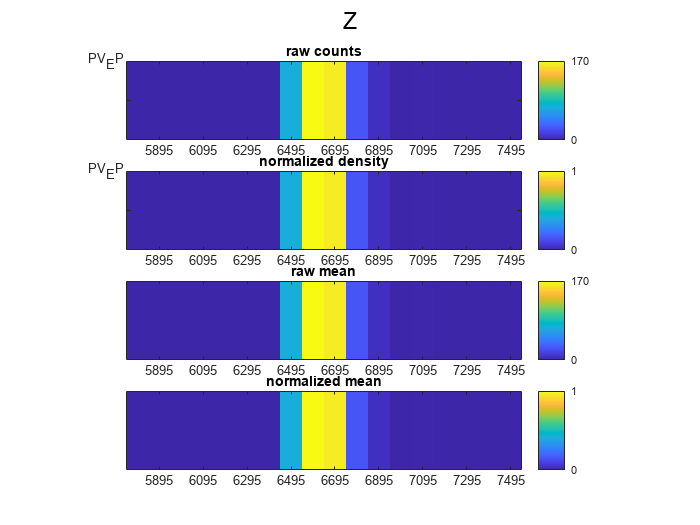

z_histo_values_combined_normalized = zeros(size(z_histo_values_combined));

num_subjects = size(z_histo_values_combined,1);
for i=1:num_subjects
    new_norm = z_histo_values_combined(i,:)/max(z_histo_values_combined(i,:));
    z_histo_values_combined_normalized(i,:) = new_norm;
end

figure;
% RAW
subplot(4,1,1);
imagesc(z_histo_values_combined);
title("raw counts");
cb = colorbar;
cb.Ticks = [0,max(z_histo_values_combined(:))];
pbaspect([1 0.2 1]);
yticklabels(subjects);
xticklabels(z_bin_edges);
% NORMALIZED
subplot(4,1,2);
imagesc(z_histo_values_combined_normalized);
title("normalized density");
cb = colorbar;
cb.Ticks = [0,1];
pbaspect([1 0.2 1]);
yticklabels(subjects);
xticklabels(z_bin_edges);
%RAW MEAN
subplot(4,1,3);
z_histo_values_combined_mean = mean(z_histo_values_combined, 1);
imagesc(z_histo_values_combined_mean);
title("raw mean");
cb = colorbar;
cb.Ticks = [0,max(z_histo_values_combined(:))];
clim([0,max(z_histo_values_combined(:))])
pbaspect([1 0.2 .1]);
yticks([]);
xticklabels(z_bin_edges);
% NORMALIZED MEAN
subplot(4,1,4);
z_histo_values_combined_normalized_mean = mean(z_histo_values_combined_normalized, 1);
imagesc(z_histo_values_combined_normalized_mean);
title("normalized mean");
cb = colorbar;
cb.Ticks = [0,1];
clim([0,max(z_histo_values_combined_normalized(:))])
pbaspect([1 0.2 1]);
yticks([]);
xticklabels(z_bin_edges);
sgtitle("Z")

histo_savepath = uigetdir('data\', 'Where to save histograms');
[~, group] = fileparts(folder_path_data);
savefilename = [group, '.mat'];

cd(histo_savepath)
save( ...
    savefilename , ...
    'folder_path_data' , ...
    'group' , ...
    'x_data_combined', ...
    'y_data_combined', ...
    'z_data_combined', ...
    'x_bin_edges' , ...
    'y_bin_edges' , ...
    'z_bin_edges' , ...
    'x_histo_values_combined' , ...
    'x_histo_values_combined_mean', ...
    'x_histo_values_combined_normalized', ...
    'x_histo_values_combined_normalized_mean', ...
    'y_histo_values_combined', ...
    'y_histo_values_combined_mean', ...
    'y_histo_values_combined_normalized', ...
    'y_histo_values_combined_normalized_mean', ...
    'z_histo_values_combined', ...
    'z_histo_values_combined_mean', ...
    'z_histo_values_combined_normalized', ...
    'z_histo_values_combined_normalized_mean'...
    );
cd(home)

## **2D Averaging, Normalization, Gaussian**

**where: max color value represents the most cells found in any 2D bin across animals**

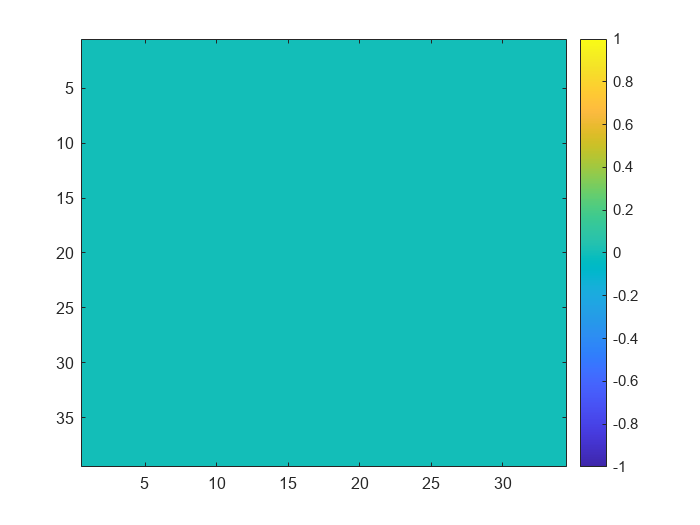

max_xy = max(xy_cells_hist_combined(:));
max_yz = max(yz_cells_hist_combined(:));
max_xz = max(xz_cells_hist_combined(:));

mean_xy_cells_hist = mean(xy_cells_hist_combined,3);
mean_yz_cells_hist = mean(yz_cells_hist_combined,3);
mean_xz_cells_hist = mean(xz_cells_hist_combined,3);

xy_cells_hist_plot = figure;
imagesc(mean_xy_cells_hist)
colormap(xy_cells_hist_plot, "parula");
cbar = colorbar;

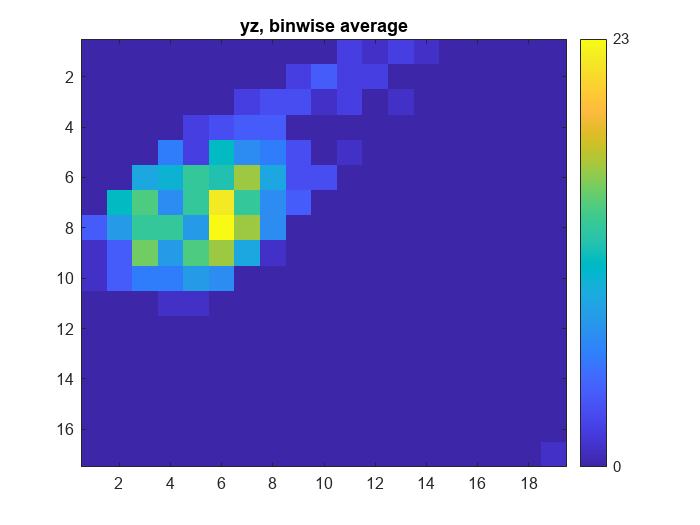

clim([0,max_xy]);
cbar.Ticks = [0,max_xy];
title("xy, binwise average")

yz_cells_hist_plot = figure;
imagesc(mean_yz_cells_hist)
colormap(yz_cells_hist_plot, "parula");
cbar = colorbar;
clim([0,max_yz]);
cbar.Ticks = [0,max_yz];
title("yz, binwise average")

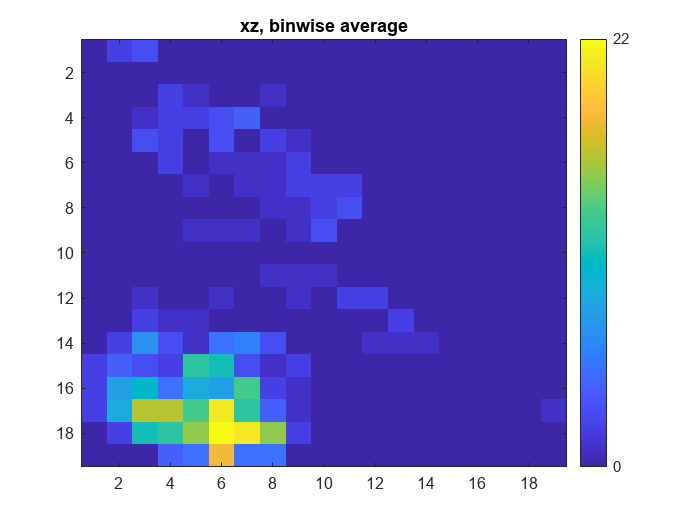


xz_cells_hist_plot = figure;
imagesc(mean_xz_cells_hist)
colormap(xz_cells_hist_plot, "parula");
cbar = colorbar;
clim([0,max_xz]);
cbar.Ticks = [0,max_xz];
title("xz, binwise average")

### Normalized

**Max color value represents normalized peak cell density**

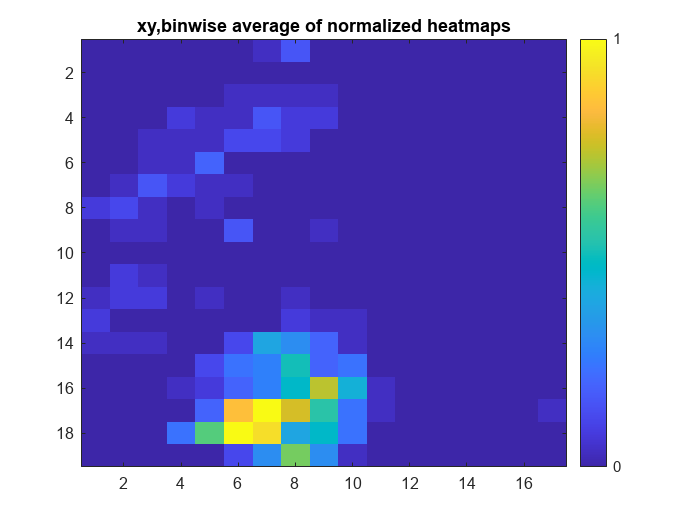

mean_xy_cells_normhist = mean(xy_cells_normhist_combined,3);
mean_yz_cells_normhist = mean(yz_cells_normhist_combined,3);
mean_xz_cells_normhist = mean(xz_cells_normhist_combined,3);

xy_cells_normhist_plot = figure;
imagesc(mean_xy_cells_normhist)
colormap(xy_cells_normhist_plot, "parula");
cbar = colorbar;
clim([0 1])
cbar.Ticks = [0,1];
title("xy,binwise average of normalized heatmaps")

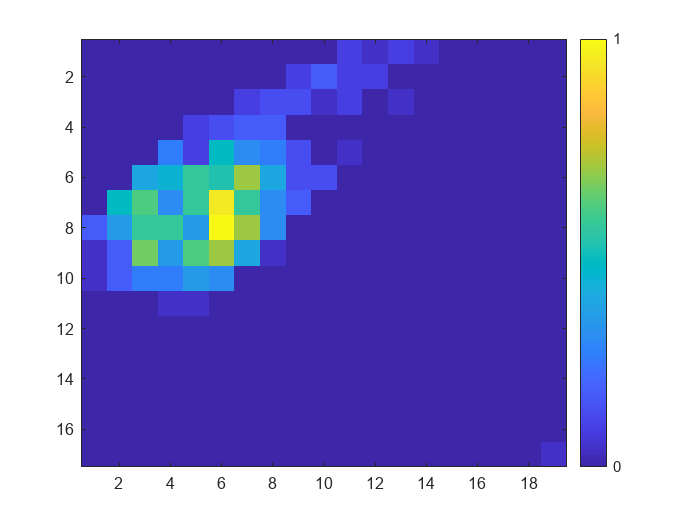


yz_cells_normhist_plot = figure;
imagesc(mean_yz_cells_normhist)
colormap(yz_cells_normhist_plot, "parula");
cbar = colorbar;
clim([0 1])
cbar.Ticks = [0,1];

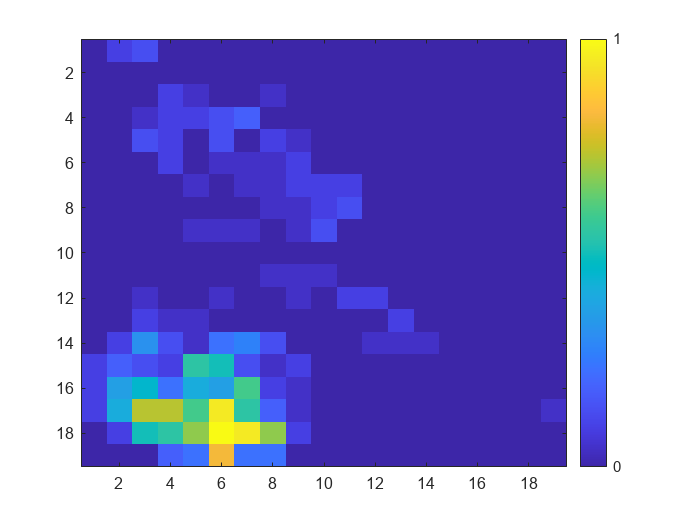


xz_cells_normhist_plot = figure;
imagesc(mean_xz_cells_normhist)
colormap(xz_cells_normhist_plot, "parula");
cbar = colorbar;
clim([0 1])
cbar.Ticks = [0,1];

### Gaussian Filtered

**Max color value represents normalized peak cell density**

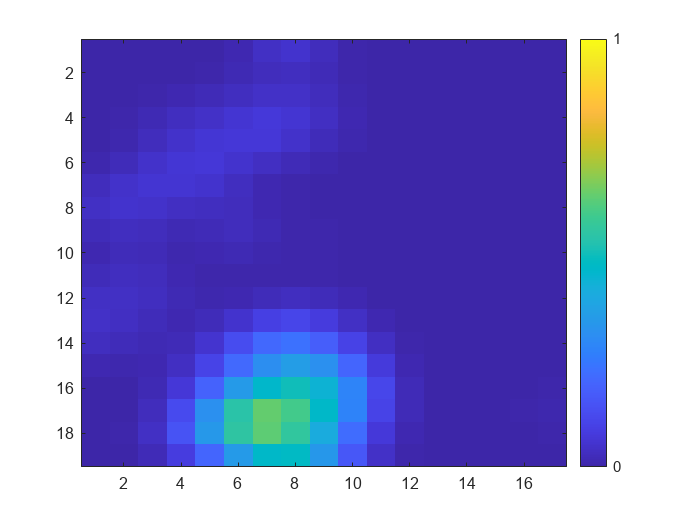

mean_xy_cells_filtered = mean(xy_cells_filtered_combined,3);
mean_yz_cells_filtered = mean(yz_cells_filtered_combined,3);
mean_xz_cells_filtered = mean(xz_cells_filtered_combined,3);


xy_cells_filtered_plot = figure;
imagesc(mean_xy_cells_filtered)
colormap(xy_cells_filtered_plot, "parula");
cbar = colorbar;
clim([0 1])
cbar.Ticks = [0,1];

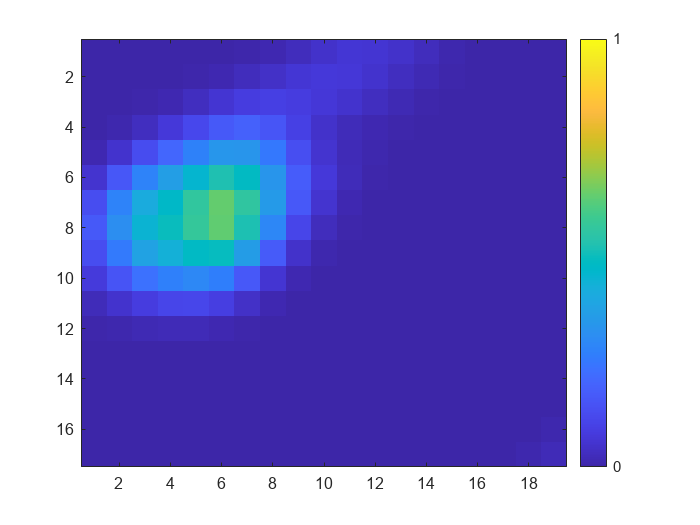


yz_cells_filtered_plot = figure;
imagesc(mean_yz_cells_filtered)
colormap(yz_cells_filtered_plot, "parula");
cbar = colorbar;
clim([0 1])
cbar.Ticks = [0,1];

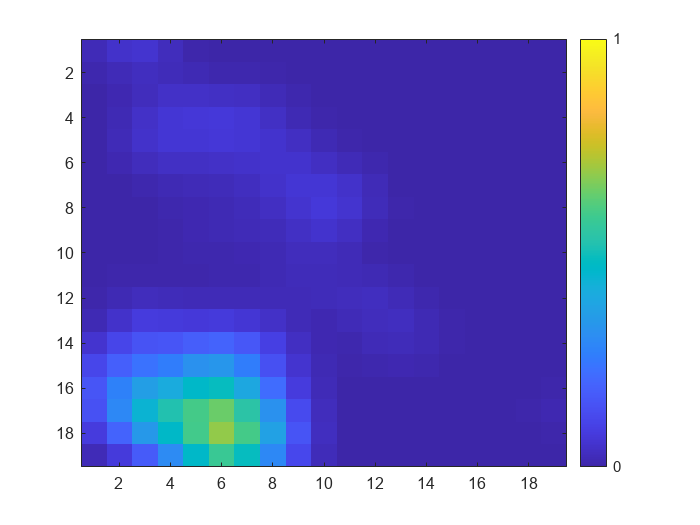


xz_cells_filtered_plot = figure;
imagesc(mean_xz_cells_filtered)
colormap(xz_cells_filtered_plot, "parula");
cbar = colorbar;
clim([0 1])
cbar.Ticks = [0,1];

## Combined Gaussian Filtered In Situ

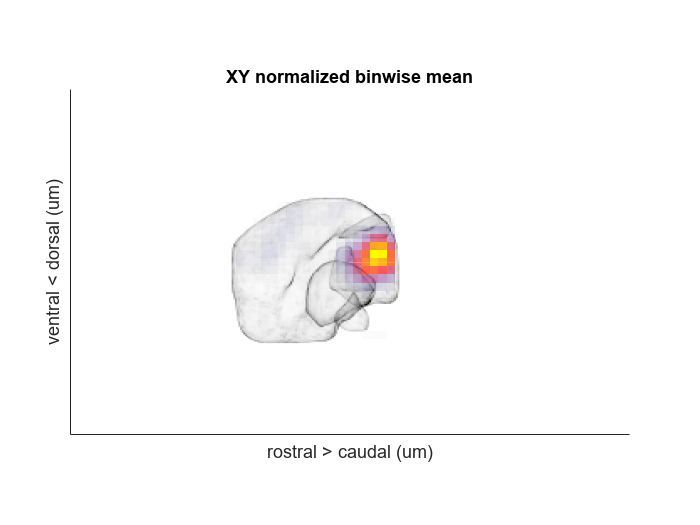

%_XY_______________________________________________________________________________________________________________
xy = figure;

xy_shadow = axes('Position', [0.1, 0.1, 0.8, 0.8]);
hist3(shadow.(side).xy, [100, 100], 'CdataMode', "auto", 'EdgeColor', 'none');
colormap(xy_shadow, shadow_map);
ylim([0, fixed.ymax]);
xlim([0, fixed.xmax]);
yticks([]);
xticks([]);
pbaspect([xaspect yaspect 1]); % [x,y,z] of plot
view(2);
set(xy_shadow, 'YDir', 'reverse');
set(xy_shadow, 'Layer', 'bottom');
grid off;
xy_reverse_gaussian = axes('Position', [0.1, 0.1, 0.8, 0.8]);
reverse_xy_hist = round(mean_xy_cells_filtered * 100);
x_range = shadow.(side).x_bounds;
y_range = shadow.(side).y_bounds;
x_edges = linspace(x_range(1), x_range(2), n_bins_x + 1);
y_edges = linspace(y_range(1), y_range(2), n_bins_y + 1);
x_centers = (x_edges(1:end-1) + x_edges(2:end)) / 2;
y_centers = (y_edges(1:end-1) + y_edges(2:end)) / 2;
reverse_x = [];
reverse_y = [];
for i = 1:n_bins_x
    for j = 1:n_bins_y
        count = reverse_xy_hist(i, j);
        if count > 0
            reverse_x = [reverse_x; repmat(x_centers(i), count, 1)];
            reverse_y = [reverse_y; repmat(y_centers(j), count, 1)];
        end
    end
end
hist3([reverse_x, reverse_y], [n_bins_x, n_bins_y],'CdataMode', "auto", 'EdgeColor', 'none');
colormap(xy_reverse_gaussian, spectrum1_map);
view(2);
surface_handle = findobj(xy_reverse_gaussian, 'Type', 'surface');
surface_handle.AlphaData = surface_handle.CData;
surface_handle.AlphaDataMapping = 'scaled';
surface_handle.FaceAlpha = 'flat';
xlabel("rostral > caudal (um)")
ylabel("ventral < dorsal (um)")
ylim([0, fixed.ymax]);
xlim([0, fixed.xmax]);
yticks([]);
xticks([]);
pbaspect([xaspect yaspect 1]); % [x,y,z] of plot
set(xy_reverse_gaussian, 'YDir', 'reverse');
set(xy_reverse_gaussian, 'Color', 'none');
title("XY normalized binwise mean")

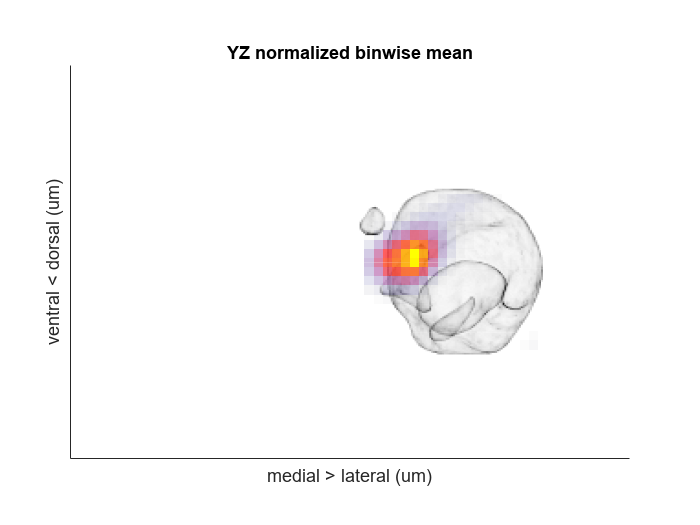


%_YZ_______________________________________________________________________________________________________________
yz = figure;

yz_shadow = axes('Position', [0.1, 0.1, 0.8, 0.8]);
hist3([shadow.(side).yz(:,2) shadow.(side).yz(:,1)], [100, 100], 'CdataMode', "auto", 'EdgeColor', 'none');
colormap(yz_shadow, shadow_map);
ylim([0 fixed.ymax]);
xlim([0 fixed.zmax]);
yticks([]);
xticks([]);
pbaspect([zaspect yaspect 1]); % [x,y,z] of plot
view(2);
set(yz_shadow, 'YDir', 'reverse');
set(yz_shadow, 'Layer', 'bottom');
grid off;
yz_reverse_gaussian = axes('Position', [0.1, 0.1, 0.8, 0.8]);
reverse_yz_hist = round(mean_yz_cells_filtered * 100);
z_range = shadow.(side).z_bounds;
y_range = shadow.(side).y_bounds;
z_edges = linspace(z_range(1), z_range(2), n_bins_z + 1);
y_edges = linspace(y_range(1), y_range(2), n_bins_y + 1);
z_centers = (z_edges(1:end-1) + z_edges(2:end)) / 2;
y_centers = (y_edges(1:end-1) + y_edges(2:end)) / 2;
reverse_z = [];
reverse_y = [];
for i = 1:n_bins_y
    for j = 1:n_bins_z
        count = reverse_yz_hist(i, j);
        if count > 0
            reverse_y = [reverse_y; repmat(y_centers(i), count, 1)];
            reverse_z = [reverse_z; repmat(z_centers(j), count, 1)];
        end
    end
end
hist3([reverse_z, reverse_y], [n_bins_z, n_bins_y],'CdataMode', "auto", 'EdgeColor', 'none');
colormap(yz_reverse_gaussian, spectrum1_map);
view(2);
surface_handle = findobj(yz_reverse_gaussian, 'Type', 'surface');
surface_handle.AlphaData = surface_handle.CData;
surface_handle.AlphaDataMapping = 'scaled';
surface_handle.FaceAlpha = 'flat';
xlabel("medial > lateral (um)")
ylabel("ventral < dorsal (um)")
ylim([0 fixed.ymax]);
xlim([0 fixed.zmax]);
yticks([]);
xticks([]);
pbaspect([zaspect yaspect 1]); % [x,y,z] of plot
set(yz_reverse_gaussian, 'YDir', 'reverse');
set(yz_reverse_gaussian, 'Color', 'none');
title("YZ normalized binwise mean")

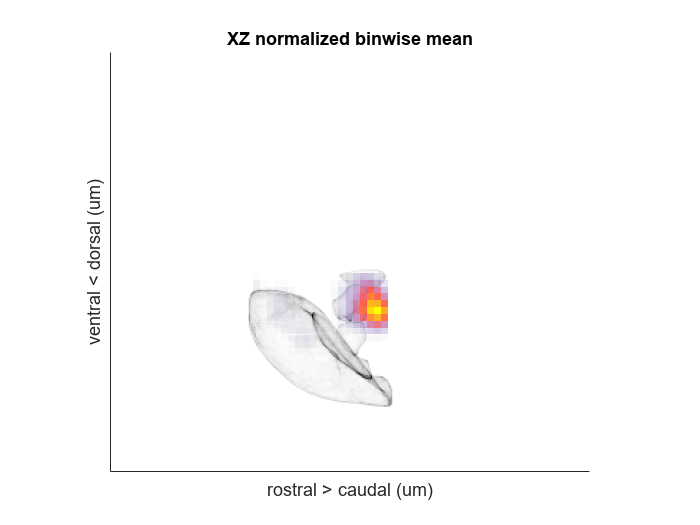


%_XZ_______________________________________________________________________________________________________________
xz = figure;

xz_shadow = axes('Position', [0.1, 0.1, 0.8, 0.8]);
hist3(shadow.(side).xz, [100, 100], 'CdataMode', "auto", 'EdgeColor', 'none');
colormap(xz_shadow, shadow_map);
ylim([0 fixed.zmax]);
xlim([0 fixed.xmax]);
yticks([]);
xticks([]);
pbaspect([1 (fixed.zmax/fixed.xmax) 1]);
view(2);
set(xz_shadow, 'YDir', 'reverse');
set(xz_shadow, 'Layer', 'bottom');
grid off;
xz_reverse_gaussian = axes('Position', [0.1, 0.1, 0.8, 0.8]);
reverse_xz_hist = round(mean_xz_cells_filtered * 100);
z_range = shadow.(side).z_bounds;
x_range = shadow.(side).x_bounds;
z_edges = linspace(z_range(1), z_range(2), n_bins_z + 1);
x_edges = linspace(x_range(1), x_range(2), n_bins_x + 1);
z_centers = (z_edges(1:end-1) + z_edges(2:end)) / 2;
x_centers = (x_edges(1:end-1) + x_edges(2:end)) / 2;
reverse_z = [];
reverse_x = [];
for i = 1:n_bins_x
    for j = 1:n_bins_z
        count = reverse_xz_hist(i, j);
        if count > 0
            reverse_x = [reverse_x; repmat(x_centers(i), count, 1)];
            reverse_z = [reverse_z; repmat(z_centers(j), count, 1)];
        end
    end
end
hist3([reverse_x, reverse_z], [n_bins_x, n_bins_z],'CdataMode', "auto", 'EdgeColor', 'none');
colormap(xz_reverse_gaussian, spectrum1_map);
view(2);
surface_handle = findobj(xz_reverse_gaussian, 'Type', 'surface');
surface_handle.AlphaData = surface_handle.CData;
surface_handle.AlphaDataMapping = 'scaled';
surface_handle.FaceAlpha = 'flat';
xlabel("rostral > caudal (um)")
ylabel("ventral < dorsal (um)")
ylim([0 fixed.zmax]);
xlim([0 fixed.xmax]);
yticks([]);
xticks([]);
pbaspect([1 (fixed.zmax/fixed.xmax) 1]);
set(xz_reverse_gaussian, 'YDir', 'reverse');
set(xz_reverse_gaussian, 'Color', 'none');
title("XZ normalized binwise mean")